## RNS and EEG Peak Latency

### Reference: 

Holm_Bonferroni Correction: David Groppe (2021). Bonferroni-Holm Correction for Multiple Comparisons (https://www.mathworks.com/matlabcentral/fileexchange/28303-bonferroni-holm-correction-for-multiple-comparisons), MATLAB Central File Exchange. Retrieved September 15, 2021.

Plotting significance stars: Rob Campbell (2021). raacampbell/sigstar (https://github.com/raacampbell/sigstar), GitHub. Retrieved September 15, 2021.

### Visual inspection

- To delete: 536JD-pz / 535BP-all / all fz

- To include: 536JD-oz-p3-760ms

addpath('R:\RNS Study\Analysis\Analysis Code\Temporal Analysis'); 
addpath('R:\RNS Study\Analysis\Analysis Code\Temporal Analysis\helper functions');

% load latency data 
cp_source = load('R:\RNS Study\Analysis\Group Analysis\Correlation Analysis\rns_cp_small.mat');


exlucde_fz = true; 

% helper functions to jitter data points in the scatter plot 
maxr =0.2; 
minr = -0.2; 
myrand = @(n) (maxr-minr).*rand(n) + minr;

% hyperparamter selection 
exclude_fz = true; % exclude fz from analysis 

eeg =cp_source.RNSEEG_CP.EEG_latency; 
rns = cp_source.RNSEEG_CP.RNS_latency; 

all_subjects = {'471MH','489RD','491GS','490KB','535BP','536JD','451NH'};
main_ch = {'oz','cz','pz','fz'}; % index corresponds to 1-4 for each of the cell of eeg. 
nsubject = 7; 

% helper functions to compute standard error 
mynumel = @(x) numel(x(~isnan(x)));
sem  = @(x) nanstd(reshape(x,[],1))/sqrt(mynumel(x));

% discard value based on visual inspection 
for ipeak = 1:4
    eeg{ipeak}(:,:,5) = NaN ; 
    eeg{ipeak}(3,:,6) = NaN ; 
    if exclude_fz
        eeg{ipeak}(4,:,:) = NaN; 
    end
end 


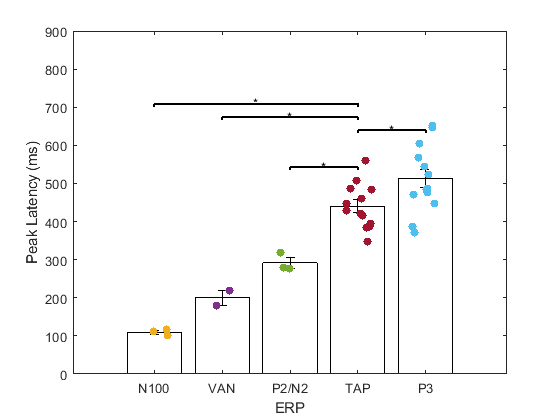

tap_group_mean = nanmean(rns{1},'all');
tap_group_sem = sem(rns{1});

total_peaks = [] ; 

% iterate through four windows of EEG and compute mean and SEM of peak
% latency 
for iw = 1:4
grp_mean(iw) = nanmean(eeg{iw},'all');
grp_sem(iw) = sem(eeg{iw});
total_peaks(end+1)= mynumel(eeg{iw}); 
end 

% add rns latency number 
total_peaks(end+1) = mynumel(rns{1}) ; 
figure; 

x = 1:5; % initialize x axis; number of peak markers 

% combine rns and eeg mean and sem of peak latency 
all_mean = [grp_mean(1:3), tap_group_mean,grp_mean(4)]; 
all_err = [grp_sem(1:3), tap_group_sem,grp_sem(4)]; 

bar(all_mean,'w');
hold on 
er = errorbar(x,all_mean,all_err,all_err);   
er.Color = [0 0 0];                            
er.LineStyle = 'none';  
xticklabels({'N100','VAN','P2/N2','TAP','P3'})

one_rns = reshape(rns{1},[],1); 

% iterate through four peaks of eeg  
for ip = 1:4
    
    one_eeg = reshape(eeg{ip},[],1); 
    
    % ranksum test against tap
    [p_val(ip),~,stats] = ranksum(one_rns,one_eeg); 
    
    if ip == 4
    ip = ip + 1 ; % move p3 after tap
    end
    scatter(repmat(ip,[1 length(one_eeg)])+myrand([1,length(one_eeg)]), one_eeg,'filled'); 
    hold on 

end 
 scatter(repmat(4,[1 length(one_rns)])+myrand([1,length(one_rns)]), one_rns,'filled'); 
 
 plot(4,rns{1}(1,:,7),'m')
 hold on 
 plot(4,rns{1}(2,:,7),'m')
 
% run holm_bonferroni correction on p values 
p_val = bonf_holm(p_val,0.05); 
 
left = sigstar({[1,4],[2,4],[3,4],[4,5]},p_val); 
set(left,'color','k')

xlabel('ERP')

ylabel('Peak Latency (ms)')
ylim([0 900]) 